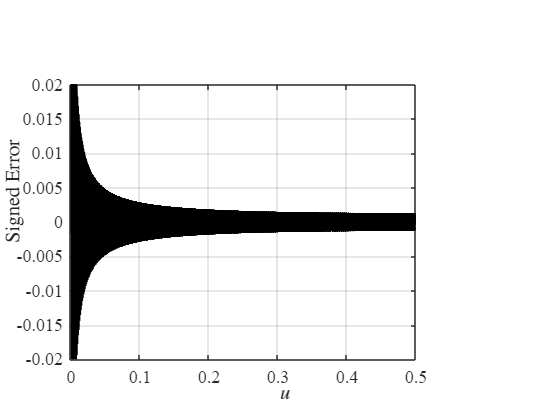

%% Method 1: Piecewise Constant Approximation on Uniform Intervals

clear; clc;

d              = 10;                           % total address bits
Nhalf          = 2^(d-1);                      % # of bins on [0, 0.5)
u_edges        = (0:Nhalf)/2^d;                % bin edges, from 0 to 0.5
nSamplesPerBin = 50;                           % samples per bin for empirical error
delta          = 1e-12;                        % avoid u=0,1
du = u_edges(2) - u_edges(1);                  % bin width (uniform)

Z = arrayfun(@(u1,u2) norminv_int(u1,u2)/(u2-u1), u_edges(1:end-1), u_edges(2:end));

all_u    = [];
all_err  = [];
maxErr   = zeros(1, Nhalf);
sumErrSq = 0;

for j = 1:Nhalf
    uL = u_edges(j)   + delta;
    uR = u_edges(j+1) - delta;
    us = linspace(uL, uR, nSamplesPerBin);
    qs = sqrt(2)*erfinv(2*us - 1);            

    errs = Z(j) - qs;

    all_u   = [all_u,   us];
    all_err = [all_err, errs];

    maxErr(j)   = max(abs(errs));
    sumErrSq    = sumErrSq + sum(errs.^2);
end

maxZ          = max(abs(Z));

% MSE Calculation
means  = arrayfun(@(a,b) norminv_int(a,b)/(b-a), u_edges(1:end-1), u_edges(2:end));
means2 = arrayfun(@(a,b) norminv2_int(a,b)/(b-a), u_edges(1:end-1), u_edges(2:end));
theoretical_MSE = sum(2* du * (means2 - means.^2));

% Plotting
u_mid = (u_edges(1:end-1) + u_edges(2:end))/2;

% Signed Error Plot
figure;
plot(all_u, all_err, 'k', 'LineWidth', 1.2);
xlabel('$u$', 'Interpreter', 'latex');   % Italic math font
ylabel('Signed Error', 'Interpreter', 'latex');
ylim([-0.02, 0.02]);
grid on;
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

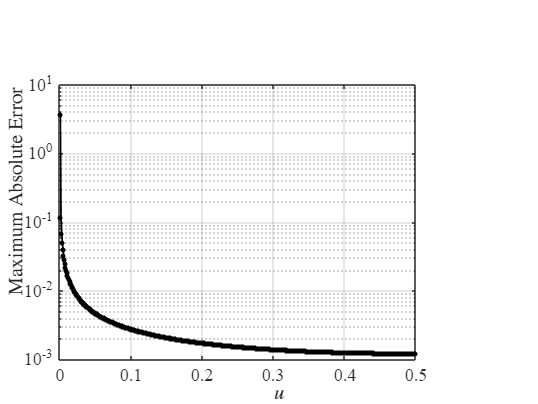

set(gcf, 'Color', 'w');

% Max Absolute Error Plot
figure;
semilogy(u_mid, maxErr, 'k.-', 'LineWidth', 1.2, 'MarkerSize', 10);
xlabel('$u$', 'Interpreter', 'latex');   % Italic math font
ylabel('Maximum Absolute Error', 'Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

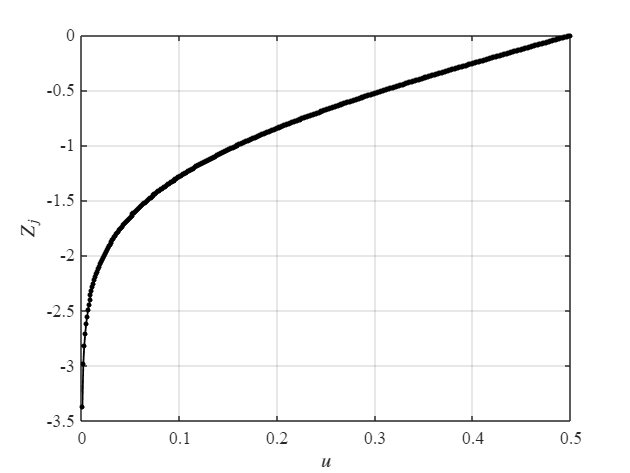

set(gcf, 'Color', 'w');

% LUT Approximation
figure;
plot(u_mid, Z, 'k.-', 'LineWidth', 1.2, 'MarkerSize', 10);
xlabel('$u$', 'Interpreter', 'latex');   % Italic math font
ylabel('$Z_j$', 'Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

set(gcf, 'Color', 'w');

fprintf('d: %d\n', d);

d: 10


fprintf('MSE:   %.3e\n', theoretical_MSE);

MSE:   1.497e-04


fprintf('Maximum absolute LUT value: %.6f\n', maxZ);

Maximum absolute LUT value: 3.373651




%%Saving as a cpp array (.h file)
fid = fopen('constant_lut_512.h', 'w');
fprintf(fid,'/* constant_lut_512.h\nPiecewise constant on uniform intervals */\n');
fprintf(fid, '#pragma once\n\n');

% Float32 LUT
fprintf(fid, 'inline constexpr float GAUSS_LUT[%d] = {', length(Z));
fprintf(fid, '%0.8gf,', Z(1:end-1));
fprintf(fid, '%0.8gf};\n\n', Z(end));

% Float16 LUT 
Z_fp16 = half(Z);

fprintf(fid, 'inline constexpr _Float16 GAUSS_LUT_FP16[%d] = {', length(Z_fp16));
for i = 1:length(Z_fp16)-1
    fprintf(fid, '%g,', double(Z_fp16(i)));
end
fprintf(fid, '%g};\n', double(Z_fp16(end)));
fclose(fid);


% Local Functions
function y = norminv_int(u1, u2)
    u1 = max(u1,1e-15);
    u2 = min(u2,1-1e-15);
    z1 = sqrt(2) * erfinv(2*u1 - 1);
    z2 = sqrt(2) * erfinv(2*u2 - 1);
    y  = normpdf(z1) - normpdf(z2);
end

function y = norminv2_int(u1, u2)
    u1 = max(u1,1e-15);
    u2 = min(u2,1-1e-15);
    z1 = sqrt(2) * erfinv(2*u1 - 1);
    z2 = sqrt(2) * erfinv(2*u2 - 1);
    y  = z1.*normpdf(z1) - z2.*normpdf(z2) + (u2-u1);
end
